imds = imageDatastore('bag', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

tbl = countEachLabel(imds);

[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');

bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: cup
* Image category 2: knife
* Image category 3: plate
* Image category 4: spoon
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 9 images...done. Extracted 1030164 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 4 has the least number of strongest features: 19315.
** Using the strongest 19315 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 77260
* Number of clusters          : 500
* Initializing cluster centers...100.


img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


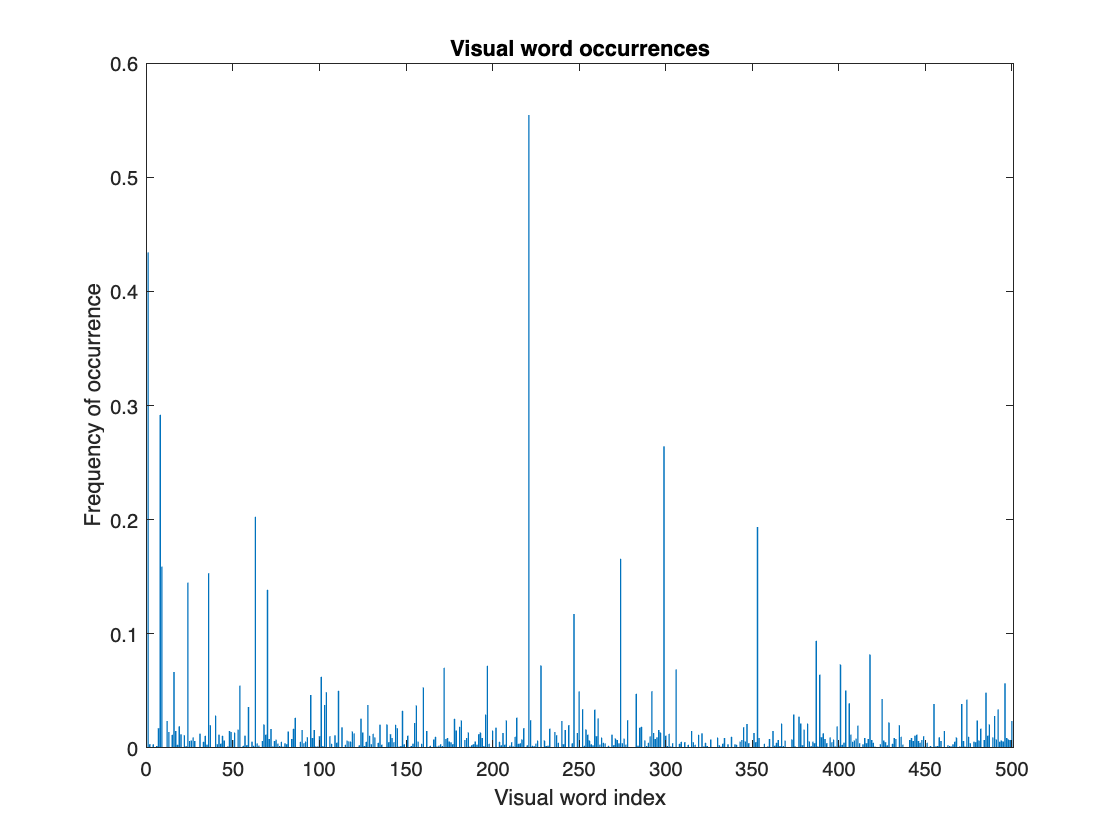


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 4 categories.
--------------------------------------------------------
* Category 1: cup
* Category 2: knife
* Category 3: plate
* Category 4: spoon

* Encoding features for 9 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 4 categories.
-------------------------------------------------------

* Category 1: cup
* Category 2: knife
* Category 3: plate
* Category 4: spoon

* Evaluating 9 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                     PREDICTED
KNOWN    | cup    knife   plate   spoon   
------------------------------------------
cup      | 1.00   0.00    0.00    0.00    
knife    | 0.00   1.00    0.00    0.00    
plate    | 0.00   0.00    1.00    0.00    
spoon    | 0.50   0.00    0.00    0.50    

* Average Accuracy is 0.88.




confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 4 categories.
-------------------------------------------------------

* Category 1: cup
* Category 2: knife
* Category 3: plate
* Category 4: spoon

* Evaluating 7 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                     PREDICTED
KNOWN    | cup    knife   plate   spoon   
------------------------------------------
cup      | 0.00   0.00    1.00    0.00    
knife    | 0.50   0.50    0.00    0.00    
plate    | 0.00   0.00    1.00    0.00    
spoon    | 1.00   0.00    0.00    0.00    

* Average Accuracy is 0.38.




% Compute average accuracy
mean(diag(confMatrix))

ans = 0.3750